% light compensation

img = imread('../TNM034/Facial-recognition/facedetection/grayworld3.png')

img = 559×451×3 uint8 array
img(:,:,1) =

    54    51    51    54    53    51    48    48    56    49    53    53    51    55    54    52    53    53    56    57    54    51    52    54    46    50    57    51    48    52    48    48    48    49    49    56    57    59    50    50    53    50    51    55    56    52    50    52    56    58    47    56    61    56    55    57    54    58    54    54    55    55    60    55    55    56    49    49    56    56    52    56    58    57    56    55    56    57    57    59    55    55    53    53    56    59    59    56    56    51    56    52    49    52    49    52    57    52    50    46    56    53    50    47    55    56    71    69    70    68    70    80    89    93   116   112   112   115   133   123   135   137   145   152   137   142   152   155   155   157   147   146   152   157   149   145   159   149   150   149   150   153   155   152   150   148   156   154   151   142   144   144   148   154   151   152   147   146   143   1

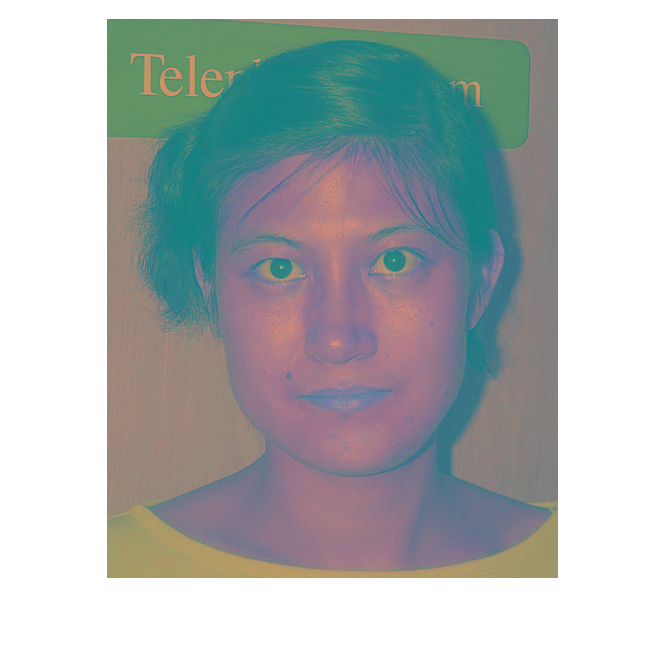



% binary image 
bin_img = zeros(size(img,1),size(img,2));

% YCbCr
YCbCr_img = rgb2ycbcr(img);
%C1 = double(YCbCr_img);
imshow(YCbCr_img);

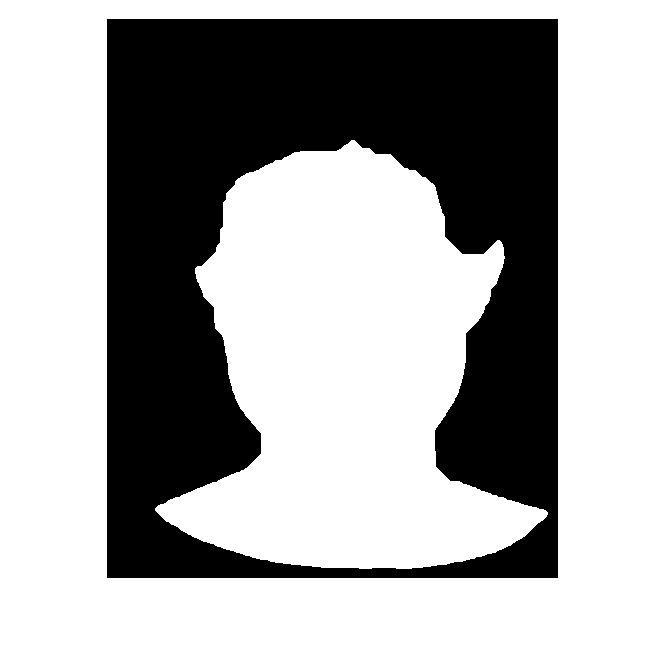


y=YCbCr_img(:,:,1);
cb=YCbCr_img(:,:,2);
cr=YCbCr_img(:,:,3);

% Threshold
[row,col] = find(cb >= 65 & cb <= 200 & cr >= 131 & cr <= 155 & y >= 80);

% Change skin color

for k = 1:size(row)
    bin_img(row(k),col(k)) = 1;
end

% Morphology
%kernel = strel('disk',20);
%bin_img = imclose(bin_img,kernel);
SE = strel('disk',4);
bin_img = imopen(bin_img, SE);
SE1 = strel('disk',25);
bin_img = imclose(bin_img, SE1);

bin_img = imfill(bin_img, 'holes');
target = 256:-4:4;
bin_img = histeq(bin_img,target);
bin_img = imbinarize(bin_img,0.9);

binary_img = bwareafilt(bin_img,1);
imshow(bin_img)